# FSI: 1DOF mechanical oscillator - State-Space system and Transfer Function

% Filip Kšica, © VUT 2025
clc;clear all;%close all;
format compact


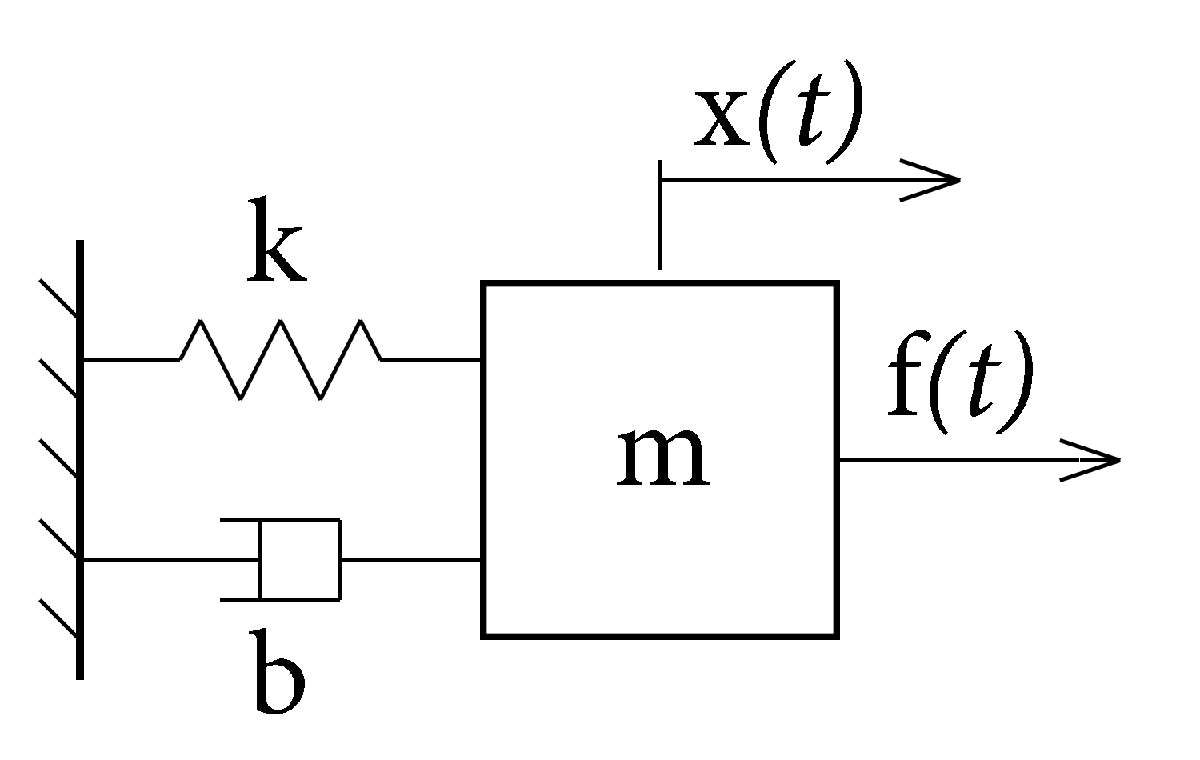

## Transfer Function 

Differential equation of motion:


$$m\ddot{x} \left(t\right)+b\dot{x} \left(t\right)+\mathrm{kx}\left(t\right)=f\left(t\right)$$


Laplace transform of the time-domain differential equation:


$$\left(ms^2 +\mathrm{bs}+\mathrm{k}\right)X\left(s\right)=F\left(s\right)$$


Transfer function is ratio of output over input, in this case mass dispalcement over excitation force:


$$\textrm{TF}=\frac{X\left(s\right)}{F\left(s\right)}=\frac{1}{ms^2 +\textrm{bs}+\mathrm{k}}$$


We can expand the fraction by $\frac{1}{m}$:


$$\textrm{TF}=\frac{X\left(s\right)}{F\left(s\right)}=\frac{\frac{1}{m}}{\frac{1}{m}\left(ms^2 +\textrm{bs}+\mathrm{k}\right)}=\frac{\frac{1}{m}}{s^2 +\frac{\mathrm{b}}{m}\mathrm{s}+\frac{\mathrm{k}}{m}}$$


If we input the definition of damping factor $\delta =\frac{b}{2m}=\xi \omega_0$ and natural frequency $\omega_0 =\sqrt{\frac{k}{m}}$, we finalize the transfer function format to:


$$\mathrm{TF}=\frac{X\left(s\right)}{F\left(s\right)}=\frac{\frac{1}{m}}{s^2 +2\xi \omega_0 \mathrm{s}+{\omega_0 }^2 }$$


## State-Space System

For denomination purposes, let's consider the physical displacement and velocity as $q$ and $\dot{q}$ respectively, retaining the symbol $x$ for states.

Differential equation of motion:


$$m\ddot{q} \left(t\right)+b\dot{q} \left(t\right)+kq\left(t\right)=f\left(t\right)$$


The general equations describing the behavior of the state-space system are 


$$\begin{array}{l}
\dot{x} =Ax+Bu\\
y=Cx+Du
\end{array}$$


where $x$ is the state vector,$y$ is the output vector, $u$ is the input vector, $A$ is the state matrix, $B$ is the input matrix, $C$ is the output matrix and $D$ is the feedforward matrix. The state vector$x$ consists of  state variables $x_1 -x_4$, which represent displacement and velocity of individual masses in the original system, 

$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$where $\left\lbrace \begin{array}{ll}
x_1 =q & \\
x_2 =\dot{q}  & 
\end{array}\right.$

To assemble the matrices $A,B,C\;\textrm{and}\;D$, equation of motions (second order differential equations) have to be split into differential equations of first order only using newly defined state vector $x$ and no longer using original physical coordinates $q$ (similar procedure as with ode45 solver). This is necessary because the state-space equations contain only the first derivation of the state vector.


$${\dot{x} }_1 =x_2$$



$${\dot{x} }_2 =-\frac{b}{m}x_2 -\frac{k}{m}x_1 +\frac{1}{m}f\left(t\right)$$


The output vector$y$ can contain any of the states $x$, therefore will have the same dimension


$$y=\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack$$


There is one input to the system representing the force on the mass, therefore the dimension of the input vector is


$$u=f\left(t\right)$$


In this step, the given state-space equations are used to assemble state-space matrices. First equation  $\dot{x} =\textrm{Ax}+\textrm{Bu}$ will use the abovementioned set of first order differential equations


$$\left\lbrack \begin{array}{c}
{\dot{x} }_1 \\
{\dot{x} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
-\frac{k}{m} & -\frac{b}{m}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}
\end{array}\right\rbrack u$$


Second equation $y=\textrm{Cx}+\textrm{Du}$ just gives us the relation between states and outputs of the system, and matrix $C$ contains ones in those lines where the state is forwarded to output. Feedforward matrix $D$ is for majority of cases a zero matrix (no direct connection between input and output of the system). For the case where outputs contain both displacement and velocity (state $x_1$ and $x_2$), the form is


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack u$$


## Parameters

Let's define dynamic properties of the 1DOF system differently using quality factor Q and natural frequency $f_0$ instead of damping and stiffness. Quality factor is defined as $Q=\frac{1}{2\xi }$, where $\xi$ is damping ratio. Well known formula for natural frequency is $\omega_0 =\sqrt{\frac{k}{m}}$ .

**Question:** If we know, based on formula for damped natural frequency $\omega_D =\omega_0 \sqrt{1-\xi^2 }$, that a damped system "loses" its natural frequency if damping reaches or exceeds critical value of $\xi =1$, what is the respective critical quality factor?

% System parameters
disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Parameters of 1DOF system:')

Parameters of 1DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


m = 1                       % [kg] mass

m = 1

Q = 20                      % [-] quality factor

Q = 20

freq_0 = 10                 % [Hz] natural frequency

freq_0 = 10

omega_0 = 2*pi*freq_0       % [rads-1] natural frequency

omega_0 = 62.8319


b = (2*m*omega_0)/(2*Q)     % [Nsm-1] damping

b = 3.1416

k = omega_0^2*m             % [Nm-1] stiffness

k = 3.9478e+03


% b = 0.3;                 % [Nsm-1]
% k = 4e3;                 % [Nm-1]

## Excitation

Select excitation input in Simulink model, 1 - harmonic, 2 - impulse:

isel = 2; 

F = 1;  % [N] force amplitude

% Harmonic
bias = 0;
freq = 10*pi;       % [Hz] excitation frequency
omega = 2*pi*freq;  % [rads-1] 
phase = 0;          % [rad] initial phase

% Impulse
t_step = 1e-2;      % [s] width of force impulse

## Initial conditions

**Note:** The usual assumption for transfer-function in this format is zero initial conditions.

**Note:** State-Space models allow the input of non-zero initial conditions.

x_10 = 0;       % [m] initial displacement
v_10 = 0;       % [ms-1] initial velocity

## Mass and stiffness matrices

M = [m];
K = [k];

## Eigenvalues and eigenvectors

[eigenvectors_1DOF, eigenvalues_1DOF] = eig(K,M);    % similar to eig(inv(K2)*M2)

**Note:** Alternative syntax:

% [eigenvectors_1DOF, eigenvalues_1DOF] = eig(inv(K2)*M2)

## State-Space System

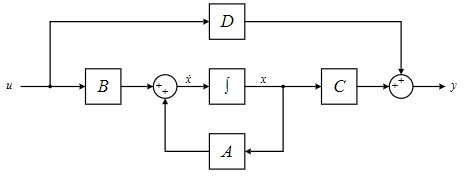

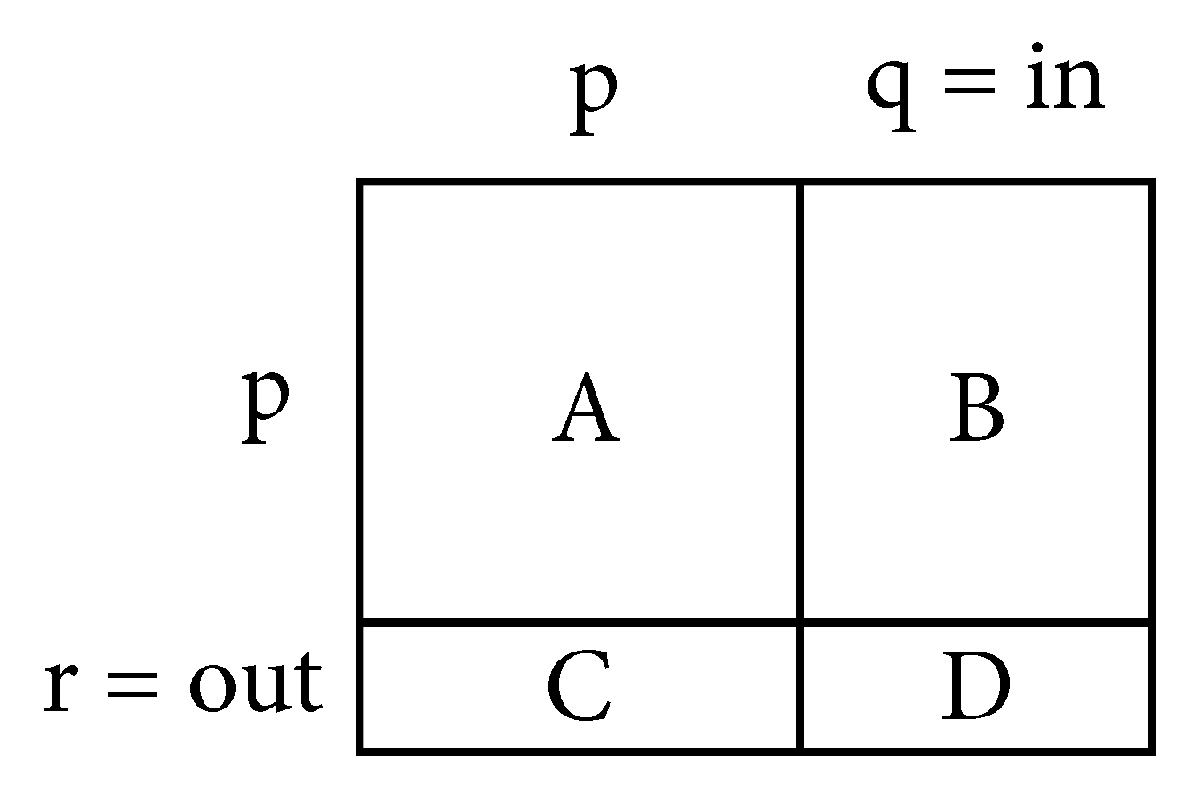


$$\begin{array}{l}
A:p\times p\;\;\;\;\textrm{state}\;\textrm{matrix}\;\\
B:p\times q\;\;\;\;\;\textrm{input}\;\textrm{matrix}\\
C:r\times p\;\;\;\;\textrm{output}\;\textrm{matrix}\\
D:r\times q\;\;\;\;\textrm{feedforward}\;\textrm{matrix}
\end{array}$$


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('State-Space matrices for 1DOF system:')

State-Space matrices for 1DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


A1 = [  0       1       ;...
        -k/m  -b/m  ]

A1 = 1.0e+03 *

         0    0.0010
   -3.9478   -0.0031


B1 = [  0       ;...    
        1/m   ]

B1 =      0
     1


C1 = eye(1,2)

C1 =      1     0


D1 = zeros(1,1)

D1 = 0

## Transfer Function

**Note: **In mechanical systems, transfer function between displacement and excitation force is *dynamic compliance* (opposite of dynamic stiffness). 

**Note:** Relation between transfer function and state space system can be written as


$$\textrm{TF}\left(s\right)=\frac{Y\left(s\right)}{U\left(s\right)}=C{\left(\textrm{sI}-A\right)}^{-1} B+D$$



$$\textrm{TF}=\frac{X\left(s\right)}{F\left(s\right)}=\frac{\frac{1}{m}}{s^2 +2\xi \omega_0 \mathrm{s}+{\omega_0 }^2 }$$


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


disp('Transfer function for 1DOF system:')

Transfer function for 1DOF system:


disp(['------------------------------------------------------------------'])

------------------------------------------------------------------


SS1DOF = ss(A1,B1,C1,D1);
[num_1DOF den_1DOF] = ss2tf(A1,B1,C1,D1);
tf_1DOF = tf(num_1DOF,den_1DOF)

tf_1DOF =
 
           1
  --------------------
  s^2 + 3.142 s + 3948
 
Continuous-time transfer function.
Model Properties


**Note: **Alternative TF syntax:

%tf_1DOF = tf([1],[m,b,k]);         % alternative tf syntax

**Note:** Finding poles and zeros of TF. Poles represent system's response to different inputs. Zeros represent frequencies that produce no output of the system.

The real part of poles represent system's damping (negative is stable) and the imaginary part represents the damped oscillation frequency.

TF_pole = pole(tf_1DOF)       % find poles of transfer function

TF_pole =   -1.5708 +62.8122i
  -1.5708 -62.8122i


TF_zero = zero(tf_1DOF)       % find zeros of transfer function

TF_zero =
  0×1 empty double column vector


**Question: **Show the location of poles and zeros in Gauss plane. Is the system stable and does it oscillate? 

## Bode diagram

Amplitude-frequency and phase-frequency characteristics.

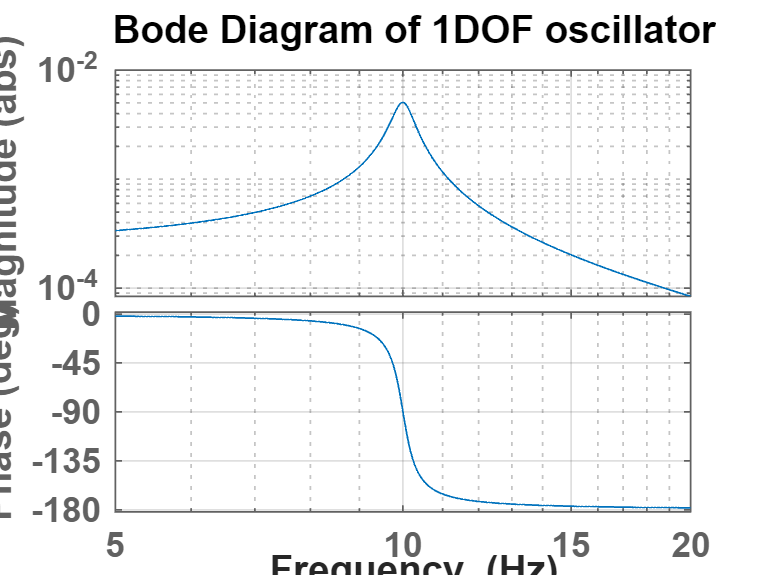

n_freq = 1e5;
freq_bode = logspace(1,3,n_freq);
bode_opt = bodeoptions('cstprefs');     % initialize plot options in the Control System and System Identification Toolbox
bode_opt.FreqUnits = 'Hz';              % set frequency units to Hz (rads-1 is default)
%bode_opt.FreqScale = 'linear';
bode_opt.MagUnits = 'abs';
bode_opt.MagScale = 'log';

figure;set(gcf,'color','w');
bode(tf_1DOF,freq_bode,bode_opt)
grid on; grid minor
xlim([5e0 2e1])
title('Bode Diagram of 1DOF oscillator')
set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 10, 'FontWeight', 'bold')


% Simulation
t_simend = 5;                   % [s] end time of simulation
simOut = sim('FSI_1DOF_SS_TF_Simulink','StopTime',num2str(t_simend));

Unable to find system or file 'FSI_1DOF_SS_TF_Simulink'.


% Save simulated data into variables
t_sim = simOut.get('t_sim');
x_1DOF = simOut.get('x_1DOF');

% Plot simulated time-domain response of 1DOF
figure;set(gcf,'color','w');
plot(t_sim,x_1DOF,'LineWidth',1);
grid on; grid minor
xlabel('time [s]')
ylabel('displacement [m]')

if isel == 1 
    title('Response of 1DOF system with harmonic force excitation','FontSize',10,'FontWeight','bold')
elseif isel == 2
    title('Response of 1DOF system with impulse force excitation','FontSize',10,'FontWeight','bold')
end

## Frequency domain response - direct approach and variable damping

Magnitude and phase of transfer function containing complex number $s=j\omega$.


$$\textrm{TF}=\frac{X\left(s\right)}{F\left(s\right)}=\frac{\frac{1}{m}}{{\left(j\omega \right)}^2 +2\xi \omega_0 j\omega +{\omega_0 }^2 }=\frac{\frac{1}{m}}{{-\omega }^2 +{\omega_0 }^2 +2\xi \omega_0 j\omega }$$




xi = [1e-3 0.025 0.2 0.5 1 2];    % [-] vector of damping ratio
omega = logspace(1,3,1e5);     % [Hz] vector of frequency
rad2deg = 180/pi;
s = j*omega;

% Create custom colormap
colors = jet(length(xi));

% Magnitude and phase
for  cnt = 1:length(xi)
	xfer(cnt,:) = (1/m) ./ (s.^2 + 2*xi(cnt)*omega_0*s + omega_0^2);
	mag(cnt,:) = abs(xfer(cnt,:));
	phs(cnt,:) = angle(xfer(cnt,:))*rad2deg;
end

figure;set(gcf,'color','w')

for  cnt = 1:length(xi)
	loglog(omega/(2*pi),mag(cnt,:),'Color',colors(cnt,:),'LineWidth',2)
        hold on        	
end
title('Frequency-domain response of 1DOF oscilaltor')
xlabel('Frequency [Hz]')
ylabel('Magnitude [abs]')
legend('\xi = 0.001','\xi = 0.025','\xi = 0.2','\xi = 0.5','\xi = 1','\xi = 2') 
xlim([5 20])
grid on; 
set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 10, 'FontWeight', 'bold')

figure;set(gcf,'color','w')
for  cnt = 1:length(xi)
	semilogx(omega/(2*pi),phs(cnt,:),'Color',colors(cnt,:),'LineWidth',2)
	hold on
end
title('Phase-domain response of 1DOF oscilaltor')
xlabel('Frequency [Hz]')
ylabel('Phase [°]')
legend('\xi = 0.001','\xi = 0.025','\xi = 0.2','\xi = 0.5','\xi = 1','\xi = 2') 
xlim([5 20])
ylim([-180 0])
grid on;
set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 10, 'FontWeight', 'bold')

## Nyquist plot

**Note:** Nyquist plot (projection to Gauss plane) is used to determine the stability of the given system.

[re,im,w] = nyquist(tf_1DOF,freq_bode);     % determine real and imaginary part of response, determine omega
re = squeeze(re);               % remove singleton dimensions
im = squeeze(im);               % remove singleton dimensions

% Plot
lim_re = [-4 4]*1e-3;
lim_im = [-6 0]*1e-3;
lim_fr = [0 20];

figure;set(gcf,'color','w')

plot3(re,im,w/(2*pi),'LineWidth',3);hold on
plot3(re,im,0*w,'-r','LineWidth',2)
plot3(re,0*im,w/(2*pi),'-m','LineWidth',2)
plot3(0*re+lim_re(2),im,w/(2*pi),'-g','LineWidth',2)
xlim(lim_re);
ylim(lim_im);
zlim(lim_fr);
xlabel('Real axis')
ylabel('Imaginary axis')
zlabel('Frequency [Hz]')
grid minor; grid on
set(gca,'Xdir','reverse')
set(gca,'Ydir','reverse')
set(findall(gcf, '-property', 'FontName'),'FontName','Arial')
set(findall(gcf, 'type','Axes'), 'FontSize', 10, 'FontWeight', 'bold')
view_azimuth = 90+45;           % [deg] view angle for 3d plot, azimuth
view_elevation = 45;            % [deg] view angle for 3d plot, elevation
view(view_azimuth, view_elevation)

legend('Nyquist plot with frequency','Projection to Gauss plane','Projection to real plane','Projection to imaginary plane','Location','SouthOutside') 
title('Nyquist plot of 1DOF TF response','FontSize',10,'FontWeight','bold')